Right, so, firstly, using Poiseuille's law, $Q=\frac{\Delta p\pi D^4 }{128\mu \text{ }L}$.

Secondly, ideal gas equation $\mathrm{PV}=\mathrm{mRT}$.

The volume of the cylinder changes as a function of time. Being a single-inlet system, the mass is also a function of time and the system is transient.

So, let $V\left(t\right)$ and $m\left(t\right)$be a function of time and the process be isothermal, then pressure inside the cylinder is given by ideal gas equation $P\left(t\right)=m\left(t\right)\frac{\mathrm{RT}}{V\left(t\right)}$.

Identifying the system as a single inlet no outlet system, we obtain $Q=\frac{\mathrm{dm}}{\mathrm{dt}}$.

So, $\frac{\mathrm{dm}}{\mathrm{dt}}=\frac{\pi D^4 }{128\mu \text{ }L}\cdot \left(P_{\mathrm{atm}} -\frac{m\left(t\right)}{V\left(t\right)}\mathrm{RT}\right)$.

Here, $V\left(t\right)$is defined function of time.

Assume atmospheric conditions.

atm=101325;
R=8314/28;
T=298;
D=0.01;
mu=1.81e-5;
L=0.1;

Load up the symbolic lab.

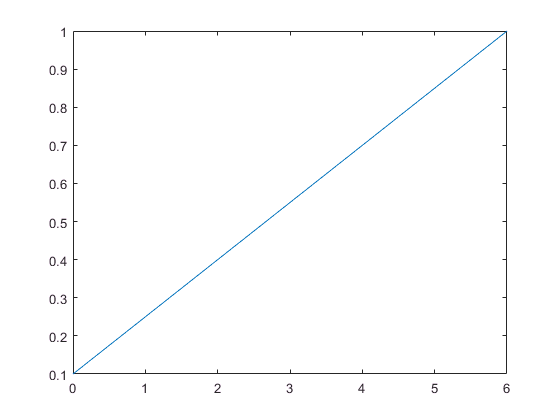

syms t m(t) V(t)
V(t)=0.1 + 0.9/6*t;
plot(0:0.1:6,V(0:0.1:6))

Dm=diff(m);

Setup the equation.

eqn=Dm==pi*D.^4/128/mu/L * (atm - m*R*T/V)

$$eqn(t) = \frac{\partial }{\partial t}m\left(t\right)=-\frac{\pi \,\left(\frac{619393\,m\left(t\right)}{7\,\left(\frac{3\,t}{20}+\frac{1}{10}\right)}-101325\right)}{23168}$$

Boundary conditions.

cond=m(0)==atm*V(0)/R/T

$$cond = m\left(0\right)=\frac{141855}{1238786}$$

Hit it: solve the equation.

sol_m=matlabFunction(dsolve(eqn, cond))

sol_m = function_handle with value:
    @(t)((2.0./3.0).^(pi.*2.546176170744541e1).*(t+2.0./3.0).^(pi.*(-2.546176170744541e1)).*8.62705368e9)./(pi.*1.918238442245e12+7.5338009376e10)+(pi.*(t+2.0./3.0).^(pi.*2.546176170744541e1+1.0).*(t+2.0./3.0).^(pi.*(-2.546176170744541e1)).*4.37348929558011)./(pi.*2.546176170744541e1+1.0)


The plotting section.

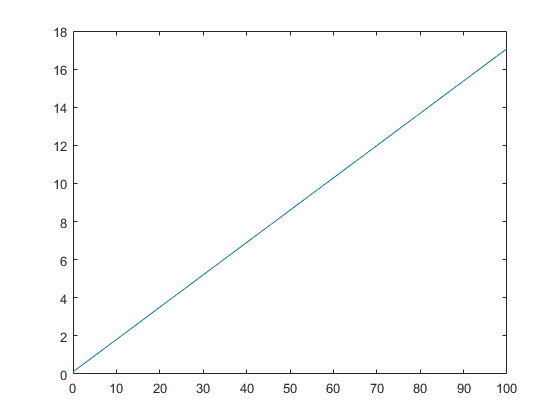

plot(0:0.1:100,sol_m(0:0.1:100))